# Example: COVID-2019 data (22-Jan-2020-15-Mar-2020)

I am taking some data from Hubei province from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Infected patient" used in the database does not precise whether they have been quarantined or not. In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('HubeiData.mat','time','Deaths','Infected','Recovered')


% If the number of confirmed infected cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
Recovered(Infected<=50)=[];
Deaths(Infected<=50)=[];
time(Infected<=50)= [];
Infected(Infected<=50)=[];



dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,04,25,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.06,1.2,1/5,1/40,0.01,0.05,0.03,0.02]; % my guess for the fit
E0 = 0; % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Infected(1); % Initial number of infectious cases (we do not know it, so it is the number of quarantined)
Q0 = 2*Infected(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Infected-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9     6.47717e+11                      7.92e+13
     1         18     1.06333e+11      0.0480551       1.01e+13      
     2         27     3.34404e+10      0.0626657       8.43e+11      
     3         36     3.34404e+10      0.0868488       8.43e+11      
     4         45     2.78935e+10      0.0217122       2.21e+11      
     5         54     2.09467e+10      0.0217122       1.25e+11      
     6         63     1.42565e+10      0.0434244       8.08e+10      
     7         72     1.09006e+10      0.0868488       5.32e+11      
     8         81     5.16634e+09      0.0868488       5.38e+10      
     9         90     3.58705e+09       0.160174        6.2e+11      
    10         99     1.47403e+09       0.115203       9.29e+09      
    11        108      1.2922e+09      0.0713595       1.26e+11      
    12        117      1.2922e+0

## Simulate the epidemy outbreak based on the fitted parameters


N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted with the real data

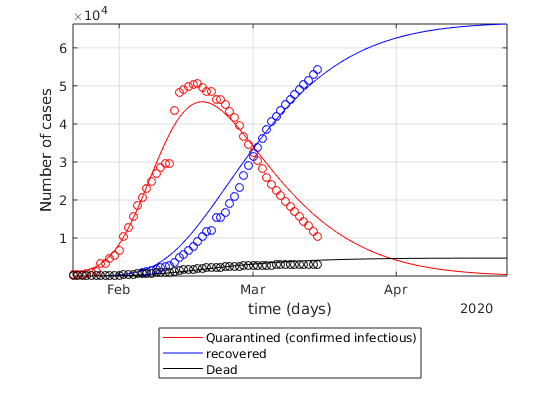

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Infected-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')